- Run preprocess_data.m first, this will take raw trajectory data, filter it, store secondary measures, such as speed, turn rates, times, etc. into separate files, all in the subject's folder for later analysis

- Run plot_traj.m next. This will plot the data for visual analysis

- Run this file next

% time to find
% hyp: time to find will depend on prior knowledge. 
timeArray = csvread('stats data/TimeToFind.csv');

timeArray(:,1)=timeArray(:,1)/2.27; % scaling to compensate for length and obstacles
t_time = array2table(timeArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
time_bp=boxplot(table2array(t_time(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Time to find (s)')
% -- define the measurements within the subjects (will  be used for all, for right now)
within=array2table([1 2 3 4]', 'variablenames', {'cond'});
rm_time=fitrm(t_time,'C1-C4~1', 'WithinDesign', within);
stats_time = ranova(rm_time)

stats_time = 2×8 table
                        SumSq    DF    MeanSq      F       pValue       pValueGG      pValueHF     pValueLB 
                        _____    __    ______    _____    _________    __________    __________    _________

    (Intercept):cond    40292     3     13431    11.69    1.778e-06    2.1367e-05    1.0175e-05    0.0019441
    Error(cond)         96503    84    1148.8                                                               


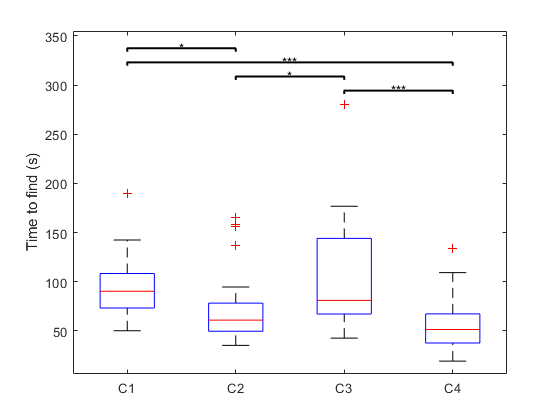

res_time = 12×7 table
    cond_1    cond_2    Difference    StdErr      pValue       Lower      Upper  
    ______    ______    __________    ______    __________    _______    ________

      1         2         22.748       7.257      0.024091      2.146       43.35
      1         3        -7.8269      10.481             1    -37.581      21.927
      1         4         39.322      6.7128    1.6112e-05     20.265      58.379
      2         1        -22.748       7.257      0.024091     -43.35      -2.146
      2         3        -30.575      10.728      0.048659     -61.03    -0.12031
      2         4         16.574      6.8058       0.12904    -2.7476      35.895
      3         1         7.8269      10.481             1    -21.927      37.581
 

if stats_time.pValue(1) < 0.05
    res_time=multcompare(rm_time, 'cond', 'ComparisonType','bonferroni')
    sigstar([],res_time,1);
end


%keyboard
% speed
% hyp: speed will depend on prior knowledge.
% higher speeds when target is known (c2 with c1, c4 with c3)
% higher speeds when map is known (c3 with c1)
EKFSpdData = csvread('stats data/RobotSpeedData.csv');
t_EKFSpd = array2table(EKFSpdData,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
EKFSpd_bp = boxplot(table2array(t_EKFSpd(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Average robot speed (m/s)')
rm_EKFSpd=fitrm(t_EKFSpd,'C1-C4~1', 'WithinDesign', within);
stats_EKFSpd = ranova(rm_EKFSpd)

stats_EKFSpd = 2×8 table
                         SumSq     DF    MeanSq       F         pValue       pValueGG      pValueHF     pValueLB 
                        _______    __    _______    ______    __________    __________    __________    _________

    (Intercept):cond    0.04668     3    0.01556    10.443    6.5521e-06    1.6876e-05    6.5521e-06    0.0031438
    Error(cond)         0.12516    84    0.00149                                                                 


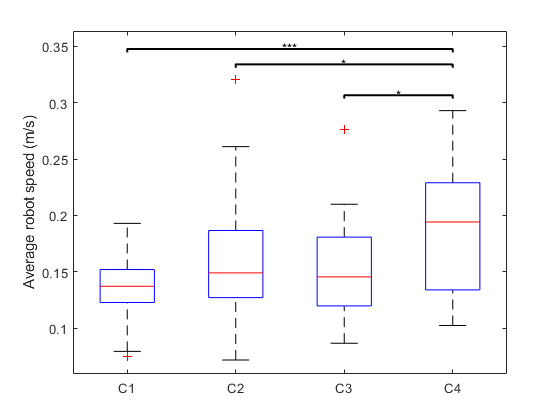

res_EKFSpd = 12×7 table
    cond_1    cond_2    Difference     StdErr        pValue        Lower         Upper   
    ______    ______    __________    _________    __________    __________    __________

      1         2       -0.022433     0.0083034      0.069491     -0.046006     0.0011395
      1         3       -0.015456     0.0091217       0.60764     -0.041352       0.01044
      1         4       -0.054994     0.0093071    1.4038e-05     -0.081416     -0.028572
      2         1        0.022433     0.0083034      0.069491    -0.0011395      0.046006
      2         3        0.006977       0.01145             1     -0.025529      0.039483
      2         4       -0.032561      0.010769      0.031803     -0.063134     -0.001987
      3         1

if stats_EKFSpd.pValue(1) < 0.05
    res_EKFSpd=multcompare(rm_EKFSpd, 'cond', 'ComparisonType','bonferroni')
    sigstar([],res_EKFSpd,1);
end



% turn rate
% hyp: turn rate will depend on prior knowledge. 
% Higher turn rate when target is not known
% no difference when map is known
EKFOmegaArray = csvread('stats data/RobotTurnrateData.csv');
t_EKFOmega = array2table(EKFOmegaArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
EKFOmega_bp = boxplot(table2array(t_EKFOmega(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Average robot turn rate (rad/s)')
rm_EKFOmega=fitrm(t_EKFOmega,'C1-C4~1', 'WithinDesign', within);
stats_EKFOmega = ranova(rm_EKFOmega)

stats_EKFOmega = 2×8 table
                        SumSq     DF    MeanSq       F        pValue     pValueGG    pValueHF    pValueLB
                        ______    __    _______    ______    ________    ________    ________    ________

    (Intercept):cond    1.5116     3    0.50386    3.2061    0.027241    0.039709    0.034934    0.084185
    Error(cond)         13.201    84    0.15716                                                          


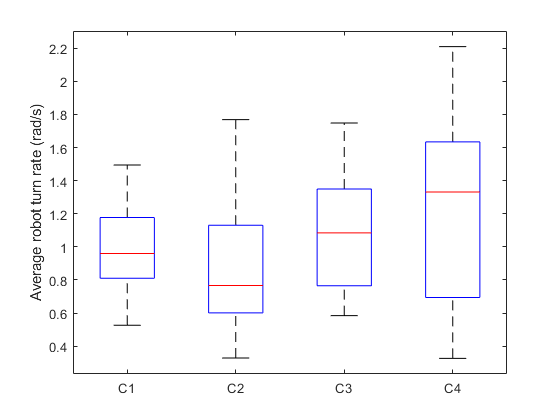

res_EKFOmega = 12×7 table
    cond_1    cond_2    Difference     StdErr     pValue       Lower       Upper  
    ______    ______    __________    ________    _______    _________    ________

      1         2        0.087183     0.092487          1     -0.17538     0.34975
      1         3        -0.11274      0.06589    0.58872      -0.2998    0.074312
      1         4        -0.21517      0.10394    0.28659     -0.51024    0.079894
      2         1       -0.087183     0.092487          1     -0.34975     0.17538
      2         3        -0.19993      0.10107    0.34706     -0.48687    0.087017
      2         4        -0.30236      0.12246    0.11949     -0.65001      0.0453
      3         1         0.11274      0.06589    0.58872    -0.074312 

if stats_EKFOmega.pValue(1) < 0.05
    res_EKFOmega=multcompare(rm_EKFOmega, 'cond', 'ComparisonType','bonferroni')
    sigstar([],res_EKFOmega,1);
end


% commanded speed
% hyp: commanded speed will depend on prior knowledge. 
% higher speeds when target is known (c2 with c1, c4 with c3)
% higher speeds when map is known (c3 with c1)
comSpeedArray = csvread('stats data/ComSpeedData.csv');
t_comSpeed = array2table(comSpeedArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
comSpeed_bp = boxplot(table2array(t_comSpeed(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Commanded speed (m/s)')
rm_comSpeed=fitrm(t_comSpeed,'C1-C4~1', 'WithinDesign', within);
stats_comSpeed = ranova(rm_comSpeed)

stats_comSpeed = 2×8 table
                         SumSq     DF      MeanSq        F         pValue       pValueGG      pValueHF     pValueLB 
                        _______    __    __________    ______    __________    __________    __________    _________

    (Intercept):cond    0.02796     3       0.00932    11.279    2.7221e-06    1.8052e-05    7.8956e-06    0.0022733
    Error(cond)         0.06941    84    0.00082631                                                                 


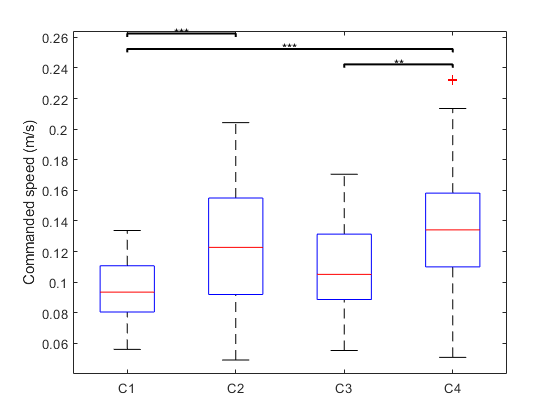

res_comSpeed = 12×7 table
    cond_1    cond_2    Difference     StdErr        pValue        Lower         Upper   
    ______    ______    __________    _________    __________    __________    __________

      1         2       -0.028955     0.0064117    0.00062418     -0.047157     -0.010753
      1         3       -0.013277     0.0054914       0.13423     -0.028867     0.0023125
      1         4       -0.041009     0.0083114    0.00019927     -0.064605     -0.017414
      2         1        0.028955     0.0064117    0.00062418      0.010753      0.047157
      2         3        0.015678      0.007368       0.25377    -0.0052397      0.036595
      2         4       -0.012054      0.009409             1     -0.038766      0.014658
      3        

if stats_comSpeed.pValue(1) < 0.05
    res_comSpeed=multcompare(rm_comSpeed, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_comSpeed, 1);
end



% commanded turn rate
% hyp: commanded turn rate will depend on prior knowledge. 
% Higher turn rate when target is not known
% no difference when map is known
comTurnRateArray = csvread('stats data/ComTurnrateData.csv');
t_comTurnRate = array2table(comTurnRateArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
comTurnRate_bp = boxplot(table2array(t_comTurnRate(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Commanded turn rate (rad/s)')
rm_comTurnRate=fitrm(t_comTurnRate,'C1-C4~1', 'WithinDesign', within);
stats_comTurnRate = ranova(rm_comTurnRate)

stats_comTurnRate = 2×8 table
                         SumSq      DF      MeanSq        F        pValue       pValueGG      pValueHF      pValueLB 
                        ________    __    __________    _____    __________    __________    __________    __________

    (Intercept):cond    0.039969     3      0.013323    15.71    3.3924e-08    2.3749e-07    6.1468e-08    0.00046319
    Error(cond)         0.071235    84    0.00084803                                                                 


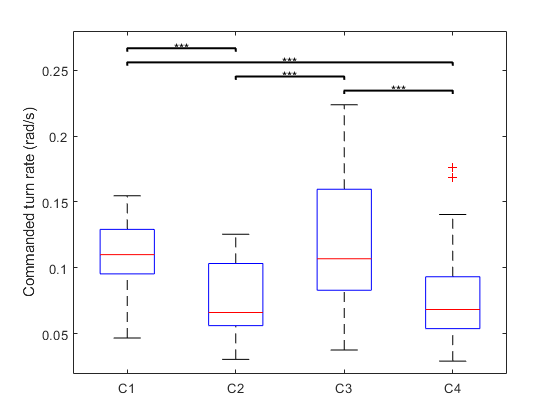

res_comTurnRate = 12×7 table
    cond_1    cond_2    Difference     StdErr        pValue        Lower        Upper  
    ______    ______    __________    _________    __________    _________    _________

      1         2         0.034673    0.0062224    3.4917e-05     0.017008     0.052338
      1         3       -0.0060331    0.0077197             1    -0.027949     0.015883
      1         4         0.033014    0.0060225    4.4667e-05     0.015916     0.050111
      2         1        -0.034673    0.0062224    3.4917e-05    -0.052338    -0.017008
      2         3        -0.040706    0.0088622    0.00050559    -0.065865    -0.015547
      2         4       -0.0016594     0.007815             1    -0.023846     0.020527
      3         1        0.0

if stats_comTurnRate.pValue(1) < 0.05
    res_comTurnRate=multcompare(rm_comTurnRate, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_comTurnRate,1)
end


% Total distance traveled
TotalDistArray = csvread('stats data/TotalDistanceTravel.csv');
TotalDistArray(:,1)=TotalDistArray(:,1)/2.27;
t_TotalDist = array2table(TotalDistArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
TotalDist_bp = boxplot(table2array(t_TotalDist(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Average total distance traveled (m)')
rm_TotalDist=fitrm(t_TotalDist,'C1-C4~1', 'WithinDesign', within);
stats_TotalDist = ranova(rm_TotalDist)

stats_TotalDist = 2×8 table
                        SumSq     DF    MeanSq      F         pValue      pValueGG     pValueHF     pValueLB
                        ______    __    ______    ______    __________    _________    _________    ________

    (Intercept):cond    663.41     3    221.14    6.5615    0.00048647    0.0025111    0.0018848    0.016095
    Error(cond)           2831    84    33.702                                                              


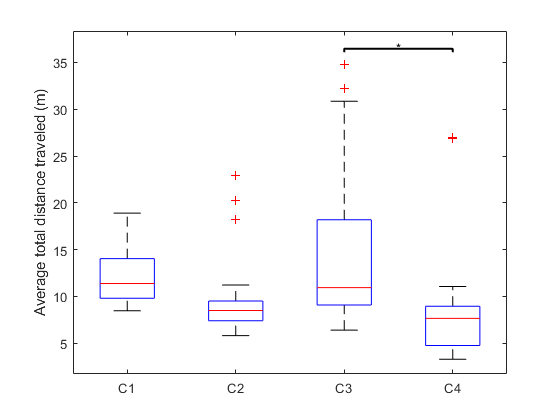

res_TotalDist = 12×7 table
    cond_1    cond_2    Difference    StdErr      pValue       Lower       Upper  
    ______    ______    __________    _______    ________    _________    ________

      1         2         2.5182      0.98214    0.096021     -0.27004      5.3064
      1         3        -2.4322       1.4986     0.69485      -6.6867      1.8223
      1         4         3.7919       1.3419     0.05161    -0.017571      7.6014
      2         1        -2.5182      0.98214    0.096021      -5.3064     0.27004
      2         3        -4.9504       1.7766    0.056755      -9.9941    0.093279
      2         4         1.2737       1.2525           1       -2.282      4.8295
      3         1         2.4322       1.4986     0.69485      -1.8223

if stats_TotalDist.pValue(1) < 0.05
    res_TotalDist=multcompare(rm_TotalDist, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_TotalDist,1)
end


% Total time in place traveled
TotalTimeInPlaceArray = csvread('stats data/TotalTimeInPlace.csv');
TotalTimeInPlaceArray(:,1)=TotalTimeInPlaceArray(:,1)/2.27;
t_TotalTimeInPlace = array2table(TotalTimeInPlaceArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
TotalDist_bp = boxplot(table2array(t_TotalTimeInPlace(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Percent time spent in place')
rm_TotalTimeInPlace=fitrm(t_TotalTimeInPlace,'C1-C4~1', 'WithinDesign', within);
stats_TotalTimeInPlace = ranova(rm_TotalTimeInPlace)

stats_TotalTimeInPlace = 2×8 table
                        SumSq     DF     MeanSq       F        pValue       pValueGG      pValueHF      pValueLB 
                        ______    __    ________    ______    _________    __________    __________    __________

    (Intercept):cond    1.9786     3     0.65952    35.503    6.441e-15    2.4592e-11    4.0273e-12    2.0468e-06
    Error(cond)         1.5604    84    0.018577                                                                 


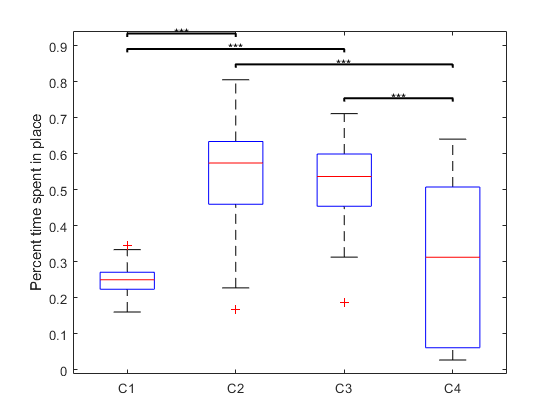

res_TotalTimeInPlace = 12×7 table
    cond_1    cond_2    Difference     StdErr       pValue        Lower       Upper  
    ______    ______    __________    ________    __________    _________    ________

      1         2         -0.28431    0.025074    3.3603e-11     -0.35549    -0.21313
      1         3         -0.27994    0.023489    1.0512e-11     -0.34663    -0.21326
      1         4        -0.045941    0.041764             1     -0.16451    0.072626
      2         1          0.28431    0.025074    3.3603e-11      0.21313     0.35549
      2         3        0.0043714    0.035095             1    -0.095262       0.104
      2         4          0.23837    0.044845    7.0288e-05      0.11106     0.36568
      3         1          0.27994    0

if stats_TotalTimeInPlace.pValue(1) < 0.05
    res_TotalTimeInPlace=multcompare(rm_TotalTimeInPlace, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_TotalTimeInPlace,1)
end



% stopping percentage (bearings)
% hyp: stopping percentage will depend on prior knowledge. 
% higher stopping percentage when map is not known
% Total time in place traveled
TotalTimeStoppingArray = csvread('stats data/TotalTimeStopping.csv');
TotalTimeStoppingArray(:,1) = TotalTimeStoppingArray(:,1)/2.27;
t_TotalTimeStoppingArray = array2table(TotalTimeStoppingArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
TotaltimeStopping_bp = boxplot(table2array(t_TotalTimeStoppingArray(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Average time collecting bearing (s)')
rm_TotalTimeStoppingArray=fitrm(t_TotalTimeStoppingArray,'C1-C4~1', 'WithinDesign', within);
stats_TotalTimeStoppingArray = ranova(rm_TotalTimeStoppingArray)

stats_TotalTimeStoppingArray = 2×8 table
                        SumSq     DF    MeanSq      F         pValue       pValueGG      pValueHF     pValueLB 
                        ______    __    ______    ______    __________    __________    __________    _________

    (Intercept):cond      2546     3    848.66    9.0228    3.0283e-05    5.1248e-05    3.0283e-05    0.0055648
    Error(cond)         7900.8    84    94.058                                                                 


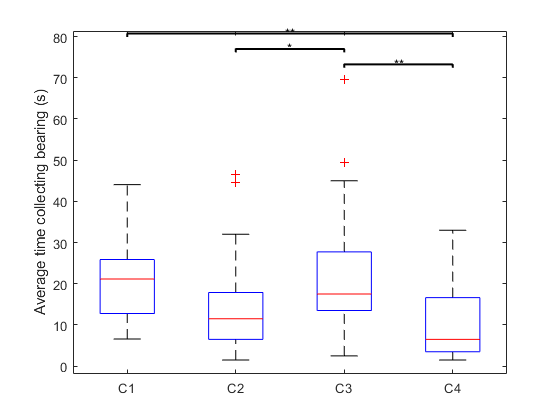

res_TotalTimeStoppingArray = 12×7 table
    cond_1    cond_2    Difference    StdErr     pValue        Lower       Upper  
    ______    ______    __________    ______    _________    _________    ________

      1         2         6.1377      2.1675      0.05088    -0.015621      12.291
      1         3        -1.6382      2.8443            1      -9.7129      6.4365
      1         4         9.9998      2.6404    0.0044469       2.5039      17.496
      2         1        -6.1377      2.1675      0.05088      -12.291    0.015621
      2         3        -7.7759       2.506     0.026087       -14.89    -0.66156
      2         4         3.8621      2.2886      0.61567      -2.6351      10.359
      3         1         1.6382      2.8443            1

if stats_TotalTimeStoppingArray.pValue(1) < 0.05
    res_TotalTimeStoppingArray=multcompare(rm_TotalTimeStoppingArray, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_TotalTimeStoppingArray,1)
end


TotalPercentStoppingArray = csvread('stats data/TotalPercentStopping.csv');
t_TotalPercentStoppingArray = array2table(TotalPercentStoppingArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
Totalpercentstopping_bp = boxplot(table2array(t_TotalPercentStoppingArray(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Percent time spent collecting bearing')
rm_TotalPercentStoppingArray=fitrm(t_TotalPercentStoppingArray,'C1-C4~1', 'WithinDesign', within);
stats_TotalPercentStoppingArray = ranova(rm_TotalPercentStoppingArray)

stats_TotalPercentStoppingArray = 2×8 table
                         SumSq     DF     MeanSq        F         pValue       pValueGG      pValueHF     pValueLB 
                        _______    __    _________    ______    __________    __________    __________    _________

    (Intercept):cond    0.13461     3     0.044871    10.442    6.5564e-06    5.4627e-05    2.7944e-05    0.0031446
    Error(cond)         0.36096    84    0.0042971                                                                 


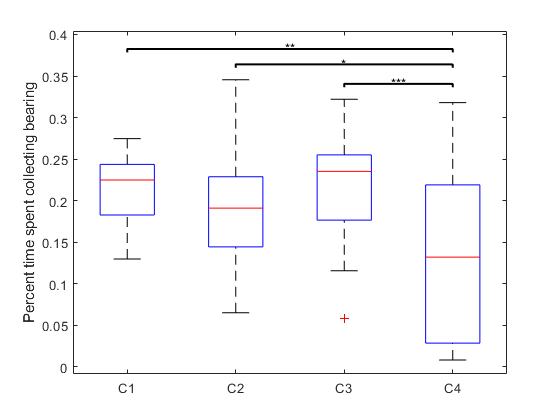

res_TotalPercentStoppingArray = 12×7 table
    cond_1    cond_2    Difference     StdErr       pValue        Lower        Upper   
    ______    ______    __________    ________    __________    _________    __________

      1         2         0.016863    0.013531             1    -0.021549      0.055275
      1         3       -0.0056272    0.013611             1    -0.044269      0.033014
      1         4         0.080059    0.021775      0.005958      0.01824       0.14188
      2         1        -0.016863    0.013531             1    -0.055275      0.021549
      2         3         -0.02249    0.015544       0.95421    -0.066618      0.021638
      2         4         0.063196    0.019454      0.018066    0.0079674       0.11843
      3       

if stats_TotalPercentStoppingArray.pValue(1) < 0.05
    res_TotalPercentStoppingArray=multcompare(rm_TotalPercentStoppingArray, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_TotalPercentStoppingArray,1)
end

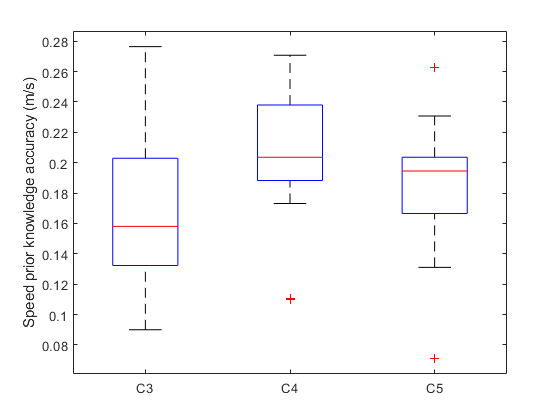



% ------------------------------------------------------------
% -- looking at only conditions 3, 4a, and 4b

% speed between 3, 4a and 4b
% knowledge of the target not present in location 1 implies it's presence in location 2, 
% thus leading to an increase in speed which resembles when target location is known in 4a
EKFSpdData = csvread('stats data/RobotSpeedData.csv');
EKFSpdData = EKFSpdData(EKFSpdData(:,5)~=0,[3,4,5]);
t_EKFSpd = array2table(EKFSpdData,...
    'VariableNames',{'C1','C2','C3'});
EKFSpd_bp = boxplot(table2array(t_EKFSpd(:,1:3)), 'labels', {'C3','C4', 'C5'});
ylabel('Speed prior knowledge accuracy (m/s)')

within3=array2table([1 2 3]', 'variablenames', {'cond'});
rm_EKFSpd=fitrm(t_EKFSpd,'C1-C3~1', 'WithinDesign', within3);
stats_EKFSpd = ranova(rm_EKFSpd)

stats_EKFSpd = 2×8 table
                          SumSq      DF     MeanSq        F       pValue     pValueGG    pValueHF    pValueLB
                        _________    __    _________    ______    _______    ________    ________    ________

    (Intercept):cond    0.0089582     2    0.0044791    2.4779    0.10352    0.10883     0.10352     0.13947 
    Error(cond)          0.046998    26    0.0018076                                                         


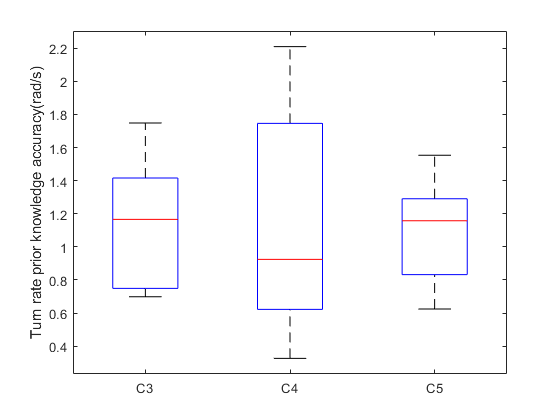

if stats_EKFSpd.pValue(1) < 0.05
    res_EKFSpd=multcompare(rm_EKFSpd, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_EKFSpd,1)
end

EKFOmegaArray = csvread('stats data/RobotTurnrateData.csv');
EKFOmegaArray = EKFOmegaArray((EKFOmegaArray(:,5) ~= 0), [3,4,5]);
t_EKFOmega = array2table(EKFOmegaArray,...
    'VariableNames',{'C1','C2','C3'});
EKFOmega_bp = boxplot(table2array(t_EKFOmega(:,1:3)), 'labels', {'C3','C4','C5'});
ylabel('Turn rate prior knowledge accuracy(rad/s)')

rm_EKFOmega=fitrm(t_EKFOmega,'C1-C3~1', 'WithinDesign', within3);
stats_EKFOmega = ranova(rm_EKFOmega)

stats_EKFOmega = 2×8 table
                         SumSq      DF     MeanSq         F        pValue    pValueGG    pValueHF    pValueLB
                        ________    __    _________    ________    ______    ________    ________    ________

    (Intercept):cond    0.010884     2    0.0054418    0.020937    0.9793    0.93405     0.94316     0.88717 
    Error(cond)           6.7578    26      0.25991                                                          


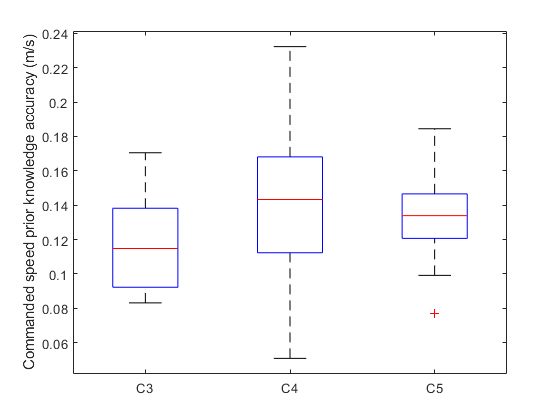

if stats_EKFOmega.pValue(1) < 0.05
    res_EKFOmega=multcompare(rm_EKFOmega, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_EKFOmega,1)
end

% commanded speed
% hyp: commanded speed will depend on prior knowledge. 
% higher speeds when target is known (c2 with c1, c4 with c3)
% higher speeds when map is known (c3 with c1)
comSpeedArray = csvread('stats data/ComSpeedData.csv');
comSpeedArray = comSpeedArray((comSpeedArray(:,5) ~= 0), [3,4,5]);
t_comSpeed = array2table(comSpeedArray,...
    'VariableNames',{'C1','C2','C3'});
comSpeed_bp = boxplot(table2array(t_comSpeed(:,1:3)), 'labels', {'C3','C4','C5'});
ylabel('Commanded speed prior knowledge accuracy (m/s)')

rm_comSpeed=fitrm(t_comSpeed,'C1-C3~1', 'WithinDesign', within3);
stats_comSpeed = ranova(rm_comSpeed)

stats_comSpeed = 2×8 table
                          SumSq      DF      MeanSq        F       pValue     pValueGG    pValueHF    pValueLB
                        _________    __    __________    ______    _______    ________    ________    ________

    (Intercept):cond    0.0043595     2     0.0021798    2.2568    0.12481    0.14069     0.13558     0.15692 
    Error(cond)          0.025112    26    0.00096585                                                         


if stats_comSpeed.pValue(1) < 0.05
    res_comSpeed=multcompare(rm_comSpeed, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_comSpeed, 1);
end


% commanded turn rate
% hyp: commanded turn rate will depend on prior knowledge. 
% Higher turn rate when target is not known
% no difference when map is known
comTurnRateArray = csvread('stats data/ComTurnrateData.csv');
comTurnRateArray = comTurnRateArray((comTurnRateArray(:,5) ~= 0), [3,4,5]);
t_comTurnRate = array2table(comTurnRateArray,...
    'VariableNames',{'C1','C2','C3'});
comTurnRate_bp = boxplot(table2array(t_comTurnRate(:,1:3)), 'labels', {'C3','C4','C5'});
ylabel('Commanded turn rate prior knowledge accuracy (rad/s)')
rm_comTurnRate=fitrm(t_comTurnRate,'C1-C3~1', 'WithinDesign', within3);
stats_comTurnRate = ranova(rm_comTurnRate)

stats_comTurnRate = 2×8 table
                         SumSq      DF     MeanSq        F        pValue      pValueGG    pValueHF    pValueLB
                        ________    __    _________    ______    _________    ________    ________    ________

    (Intercept):cond    0.024203     2     0.012102    5.9707    0.0073482    0.011125    0.008105    0.029572
    Error(cond)         0.052697    26    0.0020268                                                           


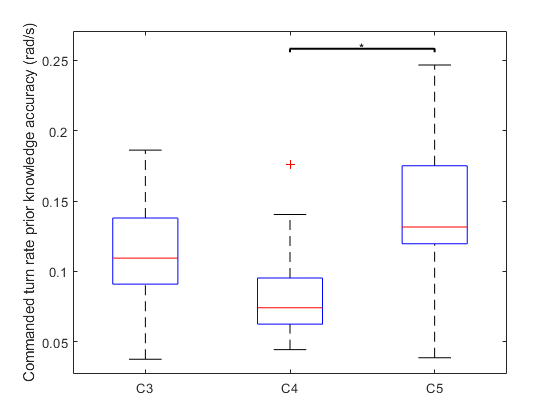

res_comTurnRate = 6×7 table
    cond_1    cond_2    Difference     StdErr      pValue       Lower        Upper   
    ______    ______    __________    ________    ________    _________    __________

      1         2        0.029423     0.014649     0.19747    -0.010802      0.069647
      1         3       -0.029379      0.01562     0.24777    -0.072271      0.013514
      2         1       -0.029423     0.014649     0.19747    -0.069647      0.010802
      2         3       -0.058801      0.02025    0.036954     -0.11441    -0.0031965
      3         1        0.029379      0.01562     0.24777    -0.013514      0.072271
      3         2        0.058801      0.02025    0.036954    0.0031965       0.11441


if stats_comTurnRate.pValue(1) < 0.05
    res_comTurnRate=multcompare(rm_comTurnRate, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_comTurnRate,1)
end




% NASA TLX
% all stats
% -- Questions that were on the NASA TLX with the corresponding value bar range
% -- Q1) Mental demand: Low - High
% -- Q2) Physical demand: Low - High
% -- Q3) Temporal demand: Low - High
% -- Q4) Performance: Perfect - Failure
% -- Q5) Effort: Low - High
% -- Q6) Frustration: Low - High

NASATLXArrayQ1 = csvread('stats data/TLX_question_1.csv');
t_NASATLXQ1 = array2table(NASATLXArrayQ1,...
    'VariableNames',{'C1','C2','C3','C4'});
NASATLXQ1_bp = boxplot(table2array(t_NASATLXQ1), 'labels', {'C1','C2','C3','C4'});
ylabel('Question response for Q1')
within2=array2table([1 2 3 4]', 'variablenames', {'cond'});
rm_NASATLXQ1=fitrm(t_NASATLXQ1,'C1-C4~1', 'WithinDesign', within2);
stats_NASATLXQ1 = ranova(rm_NASATLXQ1)

stats_NASATLXQ1 = 2×8 table
                        SumSq     DF    MeanSq      F       pValue     pValueGG    pValueHF    pValueLB
                        ______    __    ______    ______    _______    ________    ________    ________

    (Intercept):cond    2224.8     3    741.59    2.9904    0.03553    0.04506     0.039426    0.094773
    Error(cond)          20831    84    247.99                                                         


if stats_NASATLXQ1.pValue(1) < 0.05
    res_NASATLXQ1=multcompare(rm_NASATLXQ1, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_NASATLXQ1,1)
end

res_NASATLXQ1 = 12×7 table
    cond_1    cond_2    Difference    StdErr     pValue      Lower      Upper  
    ______    ______    __________    ______    ________    _______    ________

      1         2        -5.1724      4.4284           1    -17.744      7.3996
      1         3         6.2069      5.0469           1     -8.121      20.535
      1         4         4.3103      4.2165           1    -7.6599      16.281
      2         1         5.1724      4.4284           1    -7.3996      17.744
      2         3         11.379      4.2541    0.074041    -0.6977      23.456
      2         4         9.4828      3.2952    0.045506    0.12777      18.838
      3         1        -6.2069      5.0469           1    -20.535       8.121
      3       

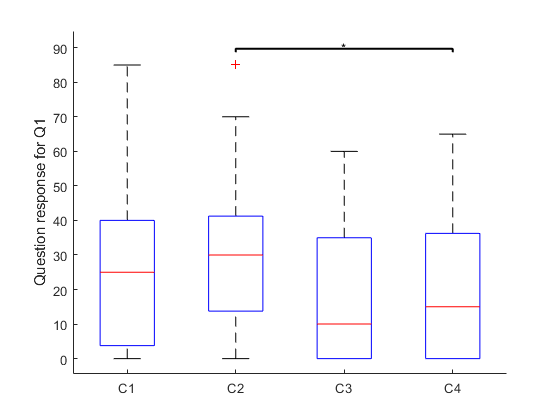

box off;


NASATLXArrayQ2 = csvread('stats data/TLX_question_2.csv');
t_NASATLXQ2 = array2table(NASATLXArrayQ2,...
    'VariableNames',{'C1','C2','C3','C4'});
NASATLXQ2_bp = boxplot(table2array(t_NASATLXQ2), 'labels', {'C1','C2','C3','C4'});
ylabel('Question response for Q2')
within2=array2table([1 2 3 4]', 'variablenames', {'cond'});
rm_NASATLXQ2=fitrm(t_NASATLXQ2,'C1-C4~1', 'WithinDesign', within2);
stats_NASATLXQ2 = ranova(rm_NASATLXQ2)

stats_NASATLXQ2 = 2×8 table
                        SumSq     DF    MeanSq      F        pValue     pValueGG    pValueHF    pValueLB
                        ______    __    ______    ______    ________    ________    ________    ________

    (Intercept):cond    1395.5     3    465.16    3.5486    0.017881    0.032788    0.029047    0.070018
    Error(cond)          11011    84    131.08                                                          


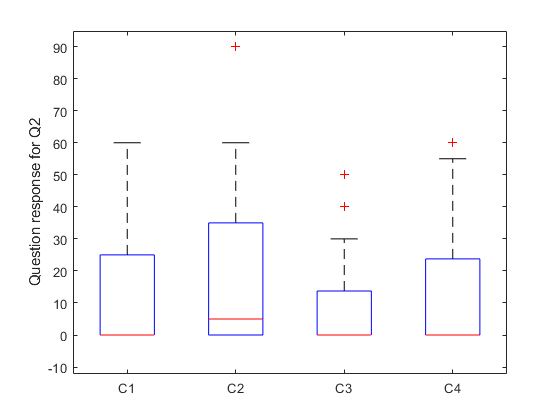

res_NASATLXQ2 = 12×7 table
    cond_1    cond_2    Difference    StdErr     pValue      Lower     Upper 
    ______    ______    __________    ______    ________    _______    ______

      1         2         -8.1034     3.0433    0.076214    -16.743    0.5364
      1         3         0.68966     3.1459           1    -8.2414    9.6207
      1         4         -3.1034     3.6166           1    -13.371    7.1638
      2         1          8.1034     3.0433    0.076214    -0.5364    16.743
      2         3          8.7931     3.4887     0.10619     -1.111    18.697
      2         4               5     2.4313     0.29497    -1.9024    11.902
      3         1        -0.68966     3.1459           1    -9.6207    8.2414
      3         2         -8.793

if stats_NASATLXQ2.pValue(1) < 0.05
    res_NASATLXQ2=multcompare(rm_NASATLXQ2, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_NASATLXQ2,1)
end


NASATLXArrayQ3 = csvread('stats data/TLX_question_3.csv');
t_NASATLXQ3 = array2table(NASATLXArrayQ3,...
    'VariableNames',{'C1','C2','C3','C4'});
NASATLXQ3_bp = boxplot(table2array(t_NASATLXQ3), 'labels', {'C1','C2','C3','C4'});
ylabel('Question response for Q3')
within2=array2table([1 2 3 4]', 'variablenames', {'cond'});
rm_NASATLXQ3=fitrm(t_NASATLXQ3,'C1-C4~1', 'WithinDesign', within2);
stats_NASATLXQ3 = ranova(rm_NASATLXQ3)

stats_NASATLXQ3 = 2×8 table
                        SumSq     DF    MeanSq      F         pValue       pValueGG      pValueHF     pValueLB
                        ______    __    ______    ______    __________    __________    __________    ________

    (Intercept):cond    6512.7     3    2170.9    7.6121    0.00014586    0.00039288    0.00022272    0.010102
    Error(cond)          23956    84    285.19                                                                


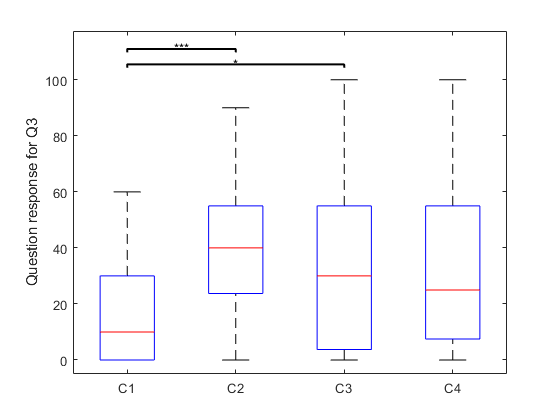

res_NASATLXQ3 = 12×7 table
    cond_1    cond_2    Difference    StdErr      pValue       Lower       Upper 
    ______    ______    __________    ______    __________    ________    _______

      1         2        -20.345      4.3261    0.00037491     -32.626    -8.0634
      1         3            -15      4.8879      0.028409     -28.876    -1.1236
      1         4        -13.448      4.9199      0.064438     -27.416    0.51912
      2         1         20.345      4.3261    0.00037491      8.0634     32.626
      2         3         5.3448      4.7663             1     -8.1863     18.876
      2         4         6.8966      4.2361       0.68829     -5.1293     18.922
      3         1             15      4.8879      0.028409      1.1236     28.

if stats_NASATLXQ3.pValue(1) < 0.05
    res_NASATLXQ3=multcompare(rm_NASATLXQ3, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_NASATLXQ3,1)
end


NASATLXArrayQ4 = csvread('stats data/TLX_question_4.csv');
t_NASATLXQ4 = array2table(NASATLXArrayQ4,...
    'VariableNames',{'C1','C2','C3','C4'});
NASATLXQ4_bp = boxplot(table2array(t_NASATLXQ4), 'labels', {'C1','C2','C3','C4'});
ylabel('Question response for Q4')
within2=array2table([1 2 3 4]', 'variablenames', {'cond'});
rm_NASATLXQ4=fitrm(t_NASATLXQ4,'C1-C4~1', 'WithinDesign', within2);
stats_NASATLXQ4 = ranova(rm_NASATLXQ4)

stats_NASATLXQ4 = 2×8 table
                        SumSq     DF    MeanSq      F        pValue     pValueGG    pValueHF    pValueLB
                        ______    __    ______    ______    ________    ________    ________    ________

    (Intercept):cond    560.99     3       187    2.7763    0.046258    0.069495    0.064823    0.10682 
    Error(cond)         5657.8    84    67.354                                                          


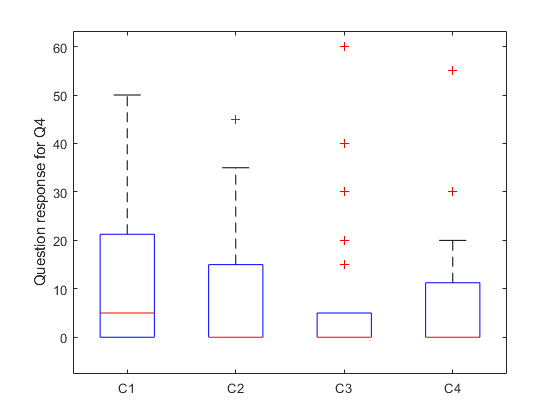

res_NASATLXQ4 = 12×7 table
    cond_1    cond_2    Difference    StdErr    pValue      Lower     Upper 
    ______    ______    __________    ______    _______    _______    ______

      1         2          3.6207     2.2593    0.72152    -2.7933    10.035
      1         3          6.0345     2.8443    0.25712    -2.0402    14.109
      1         4          4.3103     2.3109    0.43595    -2.2501    10.871
      2         1         -3.6207     2.2593    0.72152    -10.035    2.7933
      2         3          2.4138     1.6009    0.85687     -2.131    6.9586
      2         4         0.68966     1.1566          1    -2.5938    3.9731
      3         1         -6.0345     2.8443    0.25712    -14.109    2.0402
      3         2         -2.4138     1.6

if stats_NASATLXQ4.pValue(1) < 0.05
    res_NASATLXQ4=multcompare(rm_NASATLXQ4, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_NASATLXQ4,1)
end


NASATLXArrayQ5 = csvread('stats data/TLX_question_5.csv');
t_NASATLXQ5 = array2table(NASATLXArrayQ5,...
    'VariableNames',{'C1','C2','C3','C4'});
NASATLXQ5_bp = boxplot(table2array(t_NASATLXQ5), 'labels', {'C1','C2','C3','C4'});
ylabel('Question response for Q5')
within2=array2table([1 2 3 4]', 'variablenames', {'cond'});
rm_NASATLXQ5=fitrm(t_NASATLXQ5,'C1-C4~1', 'WithinDesign', within2);
stats_NASATLXQ5 = ranova(rm_NASATLXQ5)

stats_NASATLXQ5 = 2×8 table
                        SumSq     DF    MeanSq      F        pValue      pValueGG      pValueHF     pValueLB 
                        ______    __    ______    ______    ________    __________    __________    _________

    (Intercept):cond    5386.2     3    1795.4    8.4721    5.56e-05    0.00012295    5.9115e-05    0.0069979
    Error(cond)          17801    84    211.92                                                               


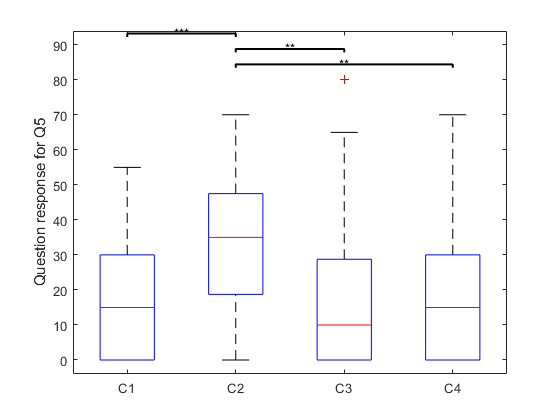

res_NASATLXQ5 = 12×7 table
    cond_1    cond_2    Difference    StdErr      pValue       Lower      Upper 
    ______    ______    __________    ______    __________    _______    _______

      1         2         -16.897     3.6081    0.00039578     -27.14    -6.6535
      1         3          -2.069      4.193             1    -13.973     9.8346
      1         4         -1.7241     4.3427             1    -14.053     10.605
      2         1          16.897     3.6081    0.00039578     6.6535      27.14
      2         3          14.828     3.8079     0.0033486     4.0172     25.638
      2         4          15.172      3.693     0.0018838     4.6883     25.657
      3         1           2.069      4.193             1    -9.8346     13.973
     

if stats_NASATLXQ5.pValue(1) < 0.05
    res_NASATLXQ5=multcompare(rm_NASATLXQ5, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_NASATLXQ5,1)
end


NASATLXArrayQ6 = csvread('stats data/TLX_question_6.csv');
t_NASATLXQ6 = array2table(NASATLXArrayQ6,...
    'VariableNames',{'C1','C2','C3','C4'});
NASATLXQ6_bp = boxplot(table2array(t_NASATLXQ6), 'labels', {'C1','C2','C3','C4'});
ylabel('Question response for Q6')
within2=array2table([1 2 3 4]', 'variablenames', {'cond'});
rm_NASATLXQ6=fitrm(t_NASATLXQ6,'C1-C4~1', 'WithinDesign', within2);
stats_NASATLXQ6 = ranova(rm_NASATLXQ6)

stats_NASATLXQ6 = 2×8 table
                        SumSq     DF    MeanSq      F       pValue     pValueGG    pValueHF    pValueLB
                        ______    __    ______    _____    ________    ________    ________    ________

    (Intercept):cond    1671.3     3    557.11    2.923    0.038605    0.043937    0.038605    0.098386
    Error(cond)          16010    84    190.59                                                         


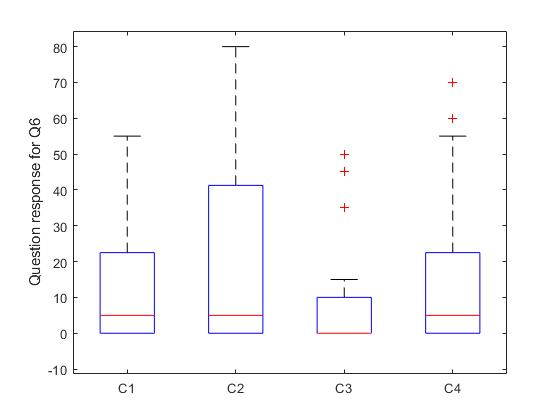

res_NASATLXQ6 = 12×7 table
    cond_1    cond_2    Difference    StdErr     pValue       Lower       Upper  
    ______    ______    __________    ______    ________    _________    ________

      1         2         -6.2069     3.9521     0.76515      -17.427      5.0129
      1         3          4.4828      3.839           1      -6.4159      15.381
      1         4        -0.51724     3.8868           1      -11.552      10.517
      2         1          6.2069     3.9521     0.76515      -5.0129      17.427
      2         3           10.69     3.7937    0.052627    -0.080299       21.46
      2         4          5.6897     2.9227     0.36999      -2.6077      13.987
      3         1         -4.4828      3.839           1      -15.381      6.4

if stats_NASATLXQ6.pValue(1) < 0.05
    res_NASATLXQ6=multcompare(rm_NASATLXQ6, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_NASATLXQ6,1)
end


% -- commanded acceleration
ComAccelArray = csvread('stats data/CommandedAccel.csv');
t_ComAccelArray = array2table(ComAccelArray,...
    'VariableNames',{'C1','C2','C3','C4','C5','SQ1','SQ2','SQ3','SQ4','SQ5'});
ComAccelArray_bp = boxplot(table2array(t_ComAccelArray(:,1:4)), 'labels', {'C1','C2','C3','C4'});
ylabel('Average percent in place (s)')
rm_ComAccelArray=fitrm(t_ComAccelArray,'C1-C4~1', 'WithinDesign', within);
stats_ComAccelArray = ranova(rm_ComAccelArray)

stats_ComAccelArray = 2×8 table
                          SumSq      DF      MeanSq        F         pValue       pValueGG      pValueHF     pValueLB 
                        _________    __    __________    ______    __________    __________    __________    _________

    (Intercept):cond     0.001777     3    0.00059234    13.017    4.6291e-07    0.00079203    0.00075578    0.0011895
    Error(cond)         0.0038225    84    4.5507e-05                                                                 


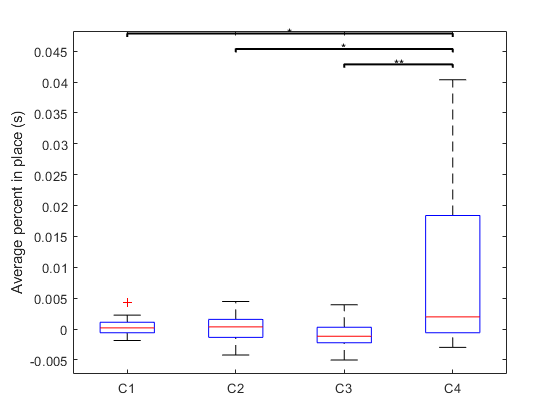

res_ComAccelArray = 12×7 table
    cond_1    cond_2    Difference       StdErr       pValue         Lower         Upper   
    ______    ______    ___________    __________    _________    ___________    __________

      1         2        5.1992e-05    0.00042303            1      -0.001149     0.0012529
      1         3         0.0012185    0.00045367     0.072152    -6.9451e-05     0.0025064
      1         4        -0.0085451     0.0024674     0.010408       -0.01555    -0.0015403
      2         1       -5.1992e-05    0.00042303            1     -0.0012529      0.001149
      2         3         0.0011665    0.00055776      0.27412    -0.00041695     0.0027499
      2         4        -0.0085971     0.0025042     0.011252      -0.015706    -0.00

if stats_ComAccelArray.pValue(1) < 0.05
    res_ComAccelArray=multcompare(rm_ComAccelArray, 'cond', 'ComparisonType','bonferroni')
    sigstar([], res_ComAccelArray,1)
end


% post trial


% we place target in a different location in 4b to see the change in behavior
% when the participant realizes that their prior knowledge is inaccurate
% we compared the actions between condition 3, when they did not have any knowledge
% of target location and condition 4b, when they again don't have knowledge about target location
% but thought they did
% 3 and 4b


% 
% % -- display all tables that contain the data from the input, tracker and
% % -- the questionnaires
% % t_time
% % t_Vel
% % t_EKFSpd
% % t_Omega
% % t_EKFOmega
% % t_TotalTimeInPlace
% % t_TotalTimeStoppingArray
% % t_TotalPercentStoppingArray
% % t_NASATLX
% % t_ComAccelArray
% 
% % -- create box plots for each of the tables, solely looking at conditions 1-4
% % -- all at the same time
% 
% 
% 
% 
% % -- apply the within to the data to get the rm
% % -- for right now solely look at conditions 1-4 without the questions
% 
% 
% % -- display the repeated measures for all data
% rm_time
% rm_Vel
% rm_EKFSpd
% rm_Omega
% rm_EKFOmega
% rm_TotalTimeInPlace
% rm_TotalTimeStoppingArray
% rm_TotalPercentStoppingArray
% rm_NASATLX
% rm_ComAccelArray
% 
% % -- after running the fit rm function, run the stats function and display it
% 
% 
% % -- check if the stats p value is below 0.05, if it is, display the
% % -- pairwise comparisons
% 




% 